#     Statistica per misura

## Setup iniziali

Inizializziamo il seme di generazione dei numeri casuali

rng(3);

Generiamo un campione di numeri casuali estratto a caso da una popolazione:

pop = random("Normal",20,0.1,100000,1);
s = randsample(pop,150);

## Istogramma

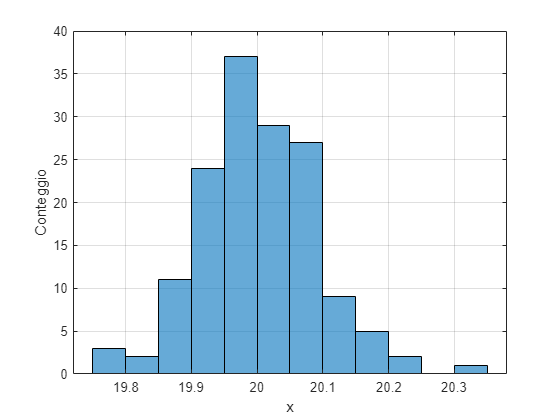

histogram(s,"Normalization","count")
xlabel("x");
ylabel("Conteggio")
grid();

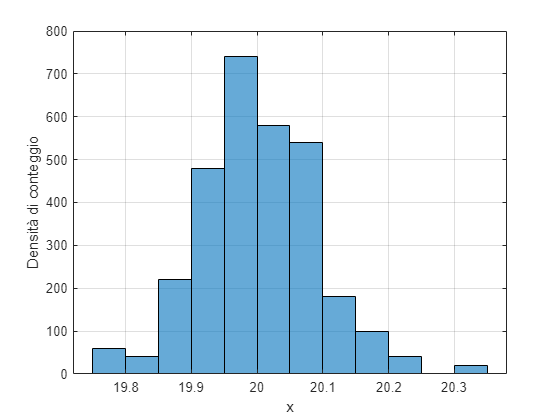

histogram(s,"Normalization","countdensity")
xlabel("x");
ylabel("Densità di conteggio")
grid();

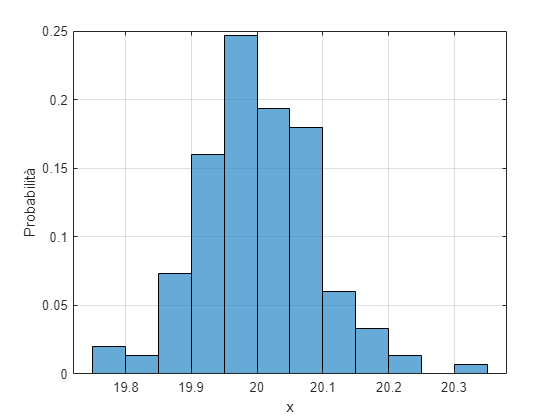

histogram(s,"Normalization","probability")
xlabel("x");
ylabel("Probabilità")
grid();

## Numero delle classi

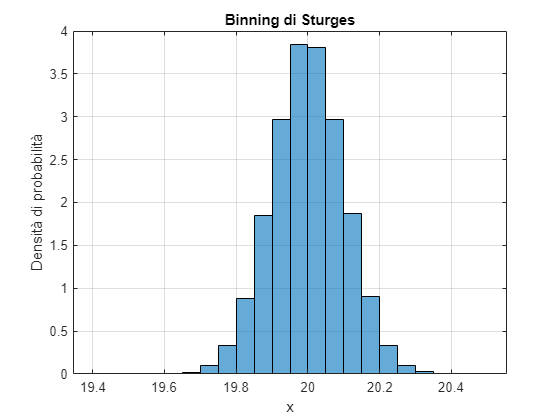

histogram(pop,"Normalization","pdf","BinMethod","sturges")
xlabel("x");
ylabel("Densità di probabilità")
title("Binning di Sturges")
grid();

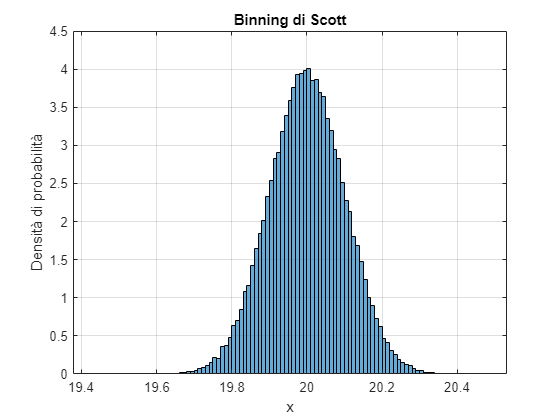

histogram(pop,"Normalization","pdf","BinMethod","scott")
xlabel("x");
ylabel("Densità di probabilità")
title("Binning di Scott")
grid();

## Cumulata

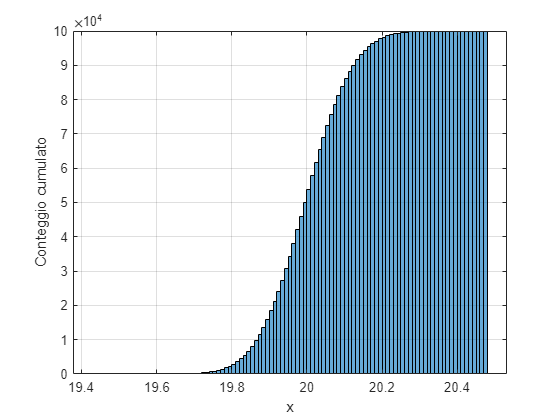

histogram(pop,"Normalization","cumcount")
xlabel("x");
ylabel("Conteggio cumulato")
grid();

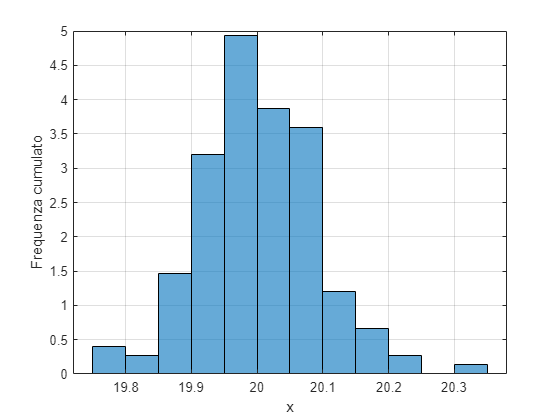

histogram(s,"Normalization","pdf")
xlabel("x");
ylabel("Frequenza cumulato")
grid();

## Funzioni di distribuzione

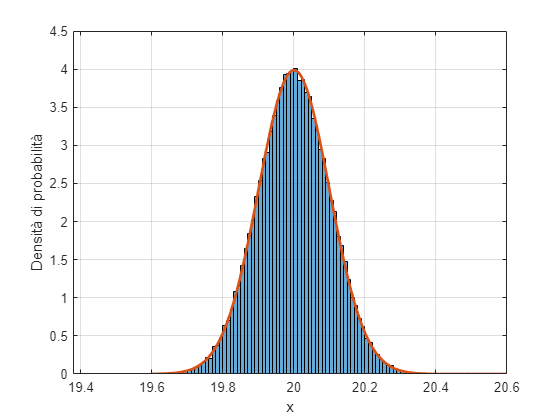

histogram(pop,"Normalization","pdf","BinMethod","scott")
xlabel("x");
ylabel("Densità di probabilità");
grid();
hold on
x = 19.6:0.01:20.6;
y = pdf("Normal", x, 20, 0.1);
plot(x,y,"LineWidth",2);
hold off

### Disribuzione uniforme

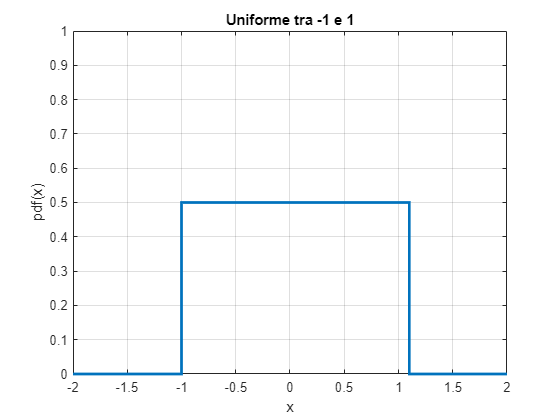

x= -2:0.1:2;
stairs(x,pdf("Uniform",x,-1,1),"LineWidth",2);
xlabel("x")
ylabel("pdf(x)")
axis([-2 2 0 1])
title("Uniforme tra -1 e 1")
grid();

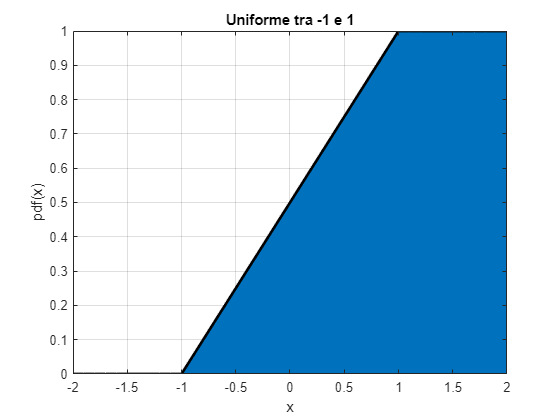

area(x,cdf("Uniform",x,-1,1),"LineWidth",2)
xlabel("x")
ylabel("pdf(x)")
axis([-2 2 0 1])
title("Uniforme tra -1 e 1")
grid();

## Distribuzione normale

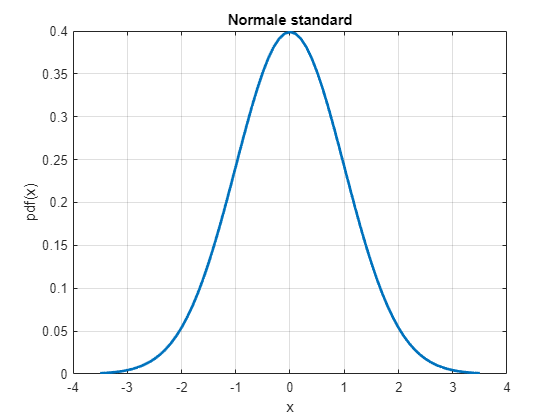

x = -3.5:0.1:3.5;
plot(x, pdf("Normal", x, 0, 1),"LineWidth",2);
xlabel("x");
ylabel("pdf(x)");
title("Normale standard")
grid();

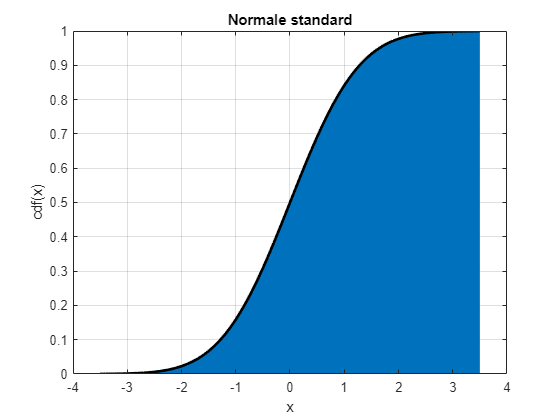

area(x, cdf("Normal", x, 0, 1),"LineWidth",2);
xlabel("x");
ylabel("cdf(x)");
title("Normale standard")
grid();

## Distribuzione Chi-quadro

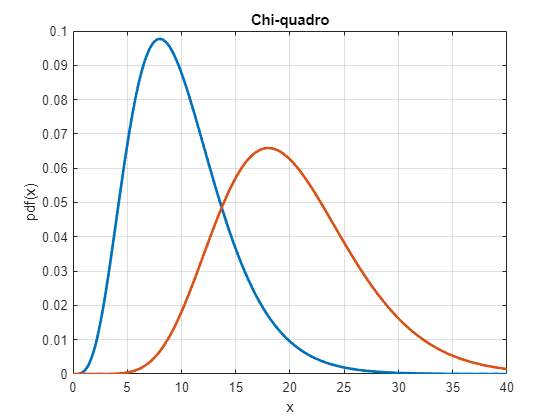

x=0:0.1:40;
plot(x, pdf("Chi-square", x, 10),"LineWidth",2);
hold on
plot(x, pdf("Chi-square", x, 20),"LineWidth",2);
hold off
xlabel("x");
ylabel("pdf(x)");
title("Chi-quadro")
grid();

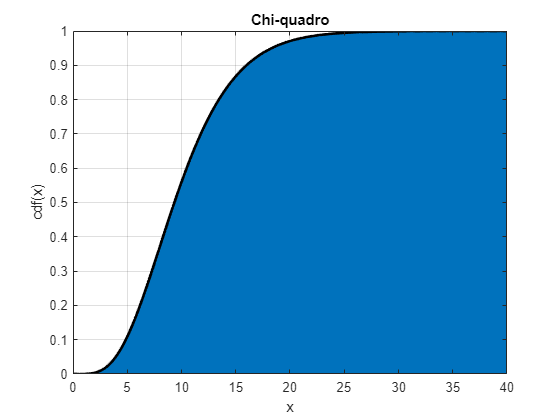

area(x, cdf("Chisquare", x, 10),"LineWidth",2);
xlabel("x");
ylabel("cdf(x)");
title("Chi-quadro")
grid();

## T di Student

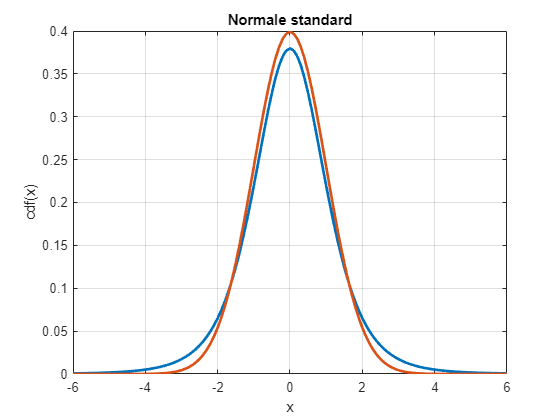

x= -6:0.1:6;
plot(x, pdf("T", x, 5),"LineWidth",2);
hold on
plot(x, pdf("Normal", x, 0, 1),"LineWidth",2);
hold off
xlabel("x");
ylabel("cdf(x)");
title("Normale standard")
grid();

## Funzione quantile

La funzione quantile è l'inversa della cdf:

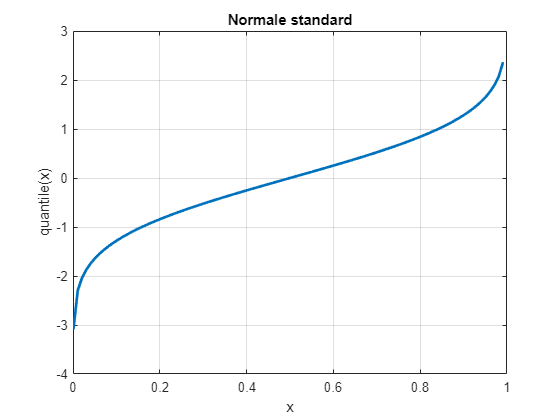

x = 0.001:0.01:9.999;
plot(x, icdf("Normal",x,0,1), "LineWidth",2)
xlabel x
ylabel quantile(x)
title ("Normale standard");
grid();

## Analisi di normalità

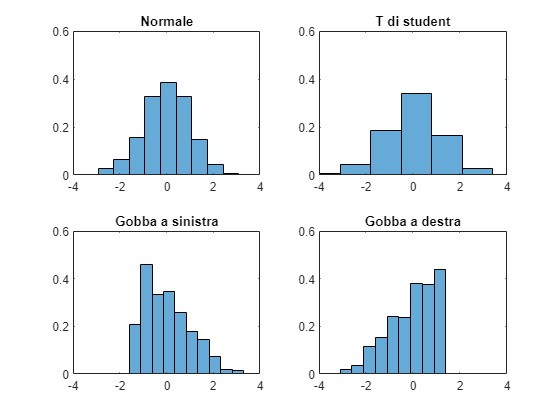

rng(11); %seme
n=500;
x1=random("Normal",0,1,n,1);
x2=random("T",5,n,1);
x3=pearsrnd(0,1,0.8,3,n,1);
x4=pearsrnd(0,1,-0.8,3,n,1);
%creo un grafico vuoto
figure
subplot(2,2,1);
histogram(x1,10,"Normalization","pdf");
title("Normale");
axis([-4 4 0 0.6]);

subplot(2,2,2);
histogram(x2,10,"Normalization","pdf");
title("T di student");
axis([-4 4 0 0.6]);

subplot(2,2,3);
histogram(x3,10,"Normalization","pdf");
title("Gobba a sinistra");
axis([-4 4 0 0.6]);

subplot(2,2,4);
histogram(x4,10,"Normalization","pdf");
title("Gobba a destra");
axis([-4 4 0 0.6]);

Costruiamo i grafici di normalità e i grafici Q-Q

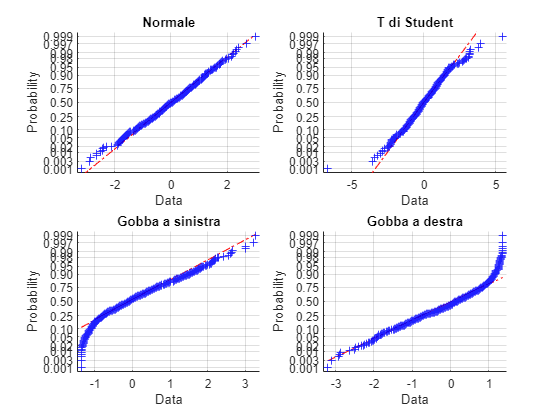

figure
subplot(2,2,1);
normplot(x1);
title("Normale")

subplot(2,2,2);
normplot(x2);
title("T di Student")

subplot(2,2,3);
normplot(x3);
title("Gobba a sinistra")

subplot(2,2,4);
normplot(x4);
title("Gobba a destra")

Se ci sono poche misure nei campioni, ci sono delle differenze sia negli istogrammi sia nei test di normalità (ad esempio, non risultano distinguibili distribuzioni normali e T di Student).

Diagrammi Quantile-Quantile

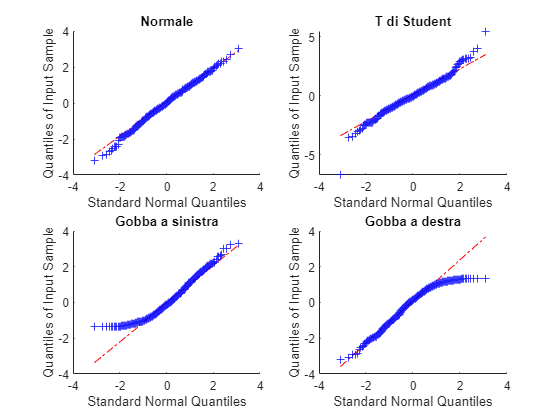

figure
subplot(2,2,1);
qqplot(x1);
title("Normale")

subplot(2,2,2);
qqplot(x2);
title("T di Student")

subplot(2,2,3);
qqplot(x3);
title("Gobba a sinistra")

subplot(2,2,4);
qqplot(x4);
title("Gobba a destra")

### Test Chi-Quadro

E' un test statistico

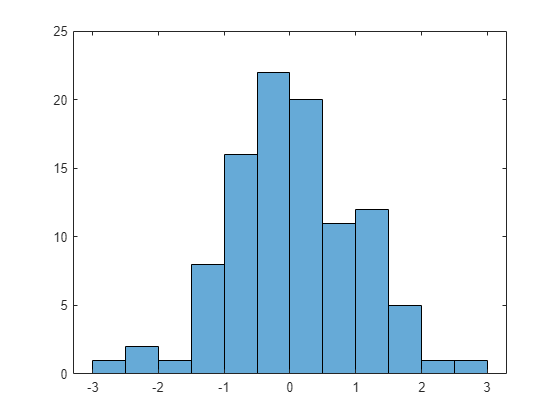

rng(12)
x=random("Normal",0,1,100,1);
figure
histogram(x);

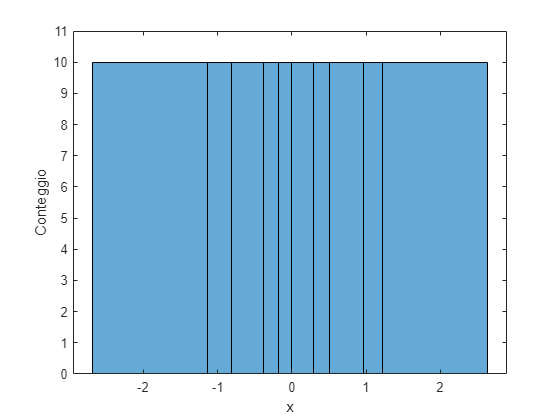

edges = [min(x),quantile(x,9),max(x)];
histogram(x, edges,"Normalization","count");
ylim([0 11]);
xlabel x;
ylabel Conteggio;

[h,p,stats]=chi2gof(x,"Edges",edges)

h = 0

p = 0.2770

stats = struct with fields:
    chi2stat: 8.6725
          df: 7
       edges: [-2.6791 -1.1315 -0.8074 -0.3855 -0.1855 -0.0019 0.2917 0.5087 0.9689 1.2240 2.6305]
           O: [10 10 10 10 10 10 10 10 10 10]
           E: [11.1499 7.6009 13.6847 7.6572 7.3863 11.8927 8.3193 14.6848 5.9354 11.6888]


O sono le osservazioni, mentre E sono i valori attesi. 

## Analisi di regressione

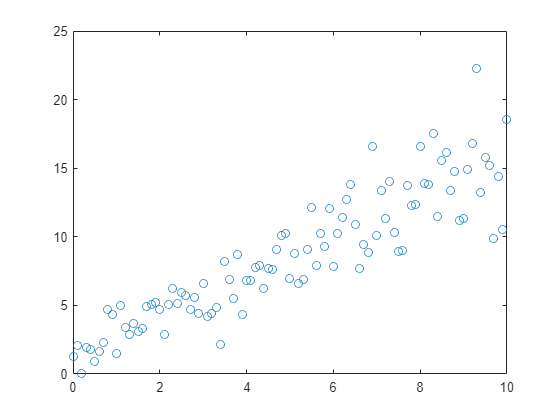

rng(0);
x = 0:0.1:10;
a = 1.5;
b = 1;
y = a*x + b;
n = random("Normal", 0, 0.5, 1, numel(x)) .* (x/2 +1); %il rumore tende ad aumentare man mano che aumenta la x
yn = y + n; %funzione con disturbo
plot(x,yn,"o")

mdl = fitlm(x',yn',"linear")

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     1.3926      0.40004    3.4812    0.00074419
    x1              1.4396     0.069117    20.828    5.8171e-38


Number of observations: 101, Error degrees of freedom: 99
Root Mean Squared Error: 2.03
R-squared: 0.814,  Adjusted R-Squared: 0.812
F-statistic vs. constant model: 434, p-value = 5.82e-38

Il comando predict consente di ottenere la regressione lineare e gli intervalli di confidenza e predizione:

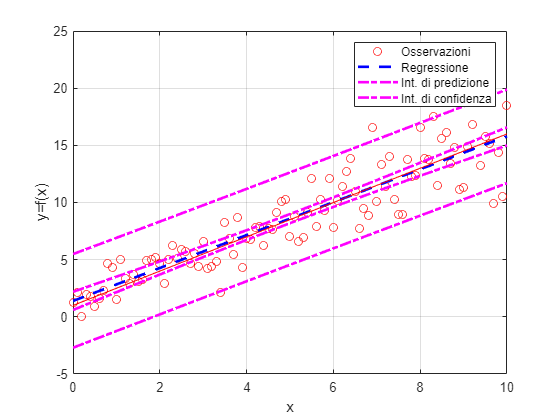

[yhat,ci]=predict(mdl,x',"Alpha",0.05,"Prediction","curve");
[yhat,cp]=predict(mdl,x',"Alpha",0.05,"Prediction","observation");

plot(x,yn,"or");
hold on
plot(x,yhat,"--b","LineWidth",2)
plot(x,cp(:,1),"-.m","LineWidth",2)
plot(x,cp(:,2),"-.m","LineWidth",2)
plot(x,ci(:,1),"-.m","LineWidth",2)
plot(x,ci(:,2),"-.m","LineWidth",2)
plot(x,y,"-r")
xlabel x;
ylabel y=f(x);
legend(["Osservazioni","Regressione","Int. di predizione","Int. di confidenza"])
grid();
hold off;

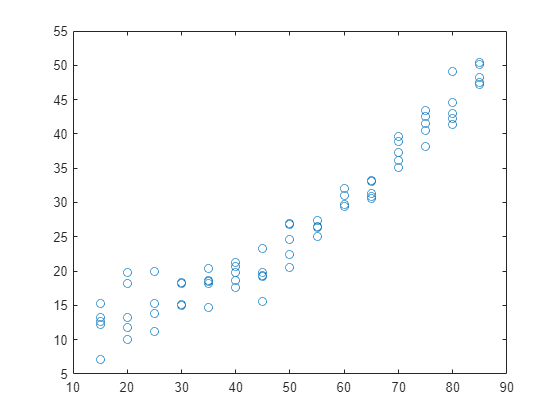

rng(0);
tbl=table();
r =5;
n=15;
a=0.005;
b=0.03;
c=10;
[i,r]=meshgrid(1:n, 1:r);
tbl.r = r(:);
tbl.i = i(:);
tbl.x = 10 + tbl.i*5;
tbl.y= a*tbl.x.^2 + b*tbl.x + c;
tbl.yn= tbl.y + random("Normal",0,2,numel(tbl.x),1);
plot(tbl.x,tbl.yn,"o")

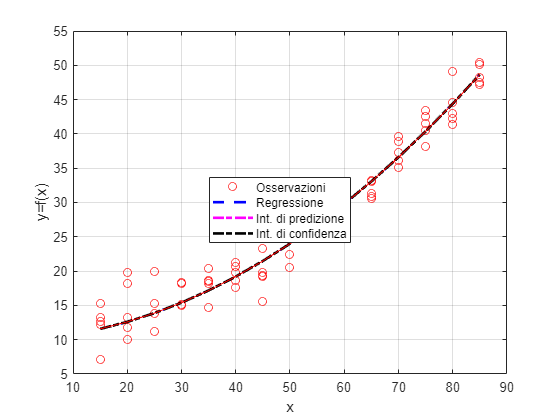

mdl= fitlm(tbl.x,tbl.y,"quadratic");
[tbl.yhat, tbl.ci]=predict(mdl,tbl.x,"Alpha",0.05,"Prediction","curve");
[tbl.yhat, tbl.cp]=predict(mdl,tbl.x,"Alpha",0.05,"Prediction","observation");

plot(tbl.x,tbl.yn,"or");
hold on
plot(tbl.x,tbl.yhat,"--b","LineWidth",2)
plot(tbl.x,tbl.cp(:,1),"-.m","LineWidth",2)
plot(tbl.x,tbl.cp(:,2),"-.k","LineWidth",2)
plot(tbl.x,tbl.ci(:,1),"-.m","LineWidth",2)
plot(tbl.x,tbl.ci(:,2),"-.k","LineWidth",2)
plot(tbl.x,tbl.y,"-r")
xlabel x;
ylabel y=f(x);
legend(["Osservazioni","Regressione","Int. di predizione","Int. di confidenza"],"Location","none")
grid();
hold off;

## Over- e Under-fitting

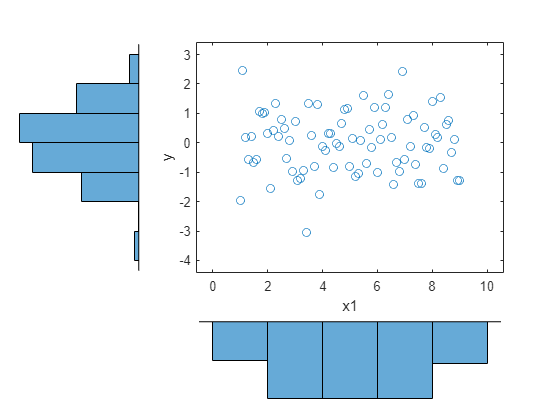

rng(0);
x=0:0.1:10;
a=-1;
b=5;
c=80;
y=a*x.^2 + b*x +c;
yn= y + random("Normal",0,1,1,numel(x));
x1=x(x >= 1 & x<=9);
y1=yn(x >= 1 & x<=9);

mdl1=fitlm(x1,y1,"poly2");
scatterhist(x1,mdl1.Residuals.Raw,"Direction","out","Location","SouthWest")

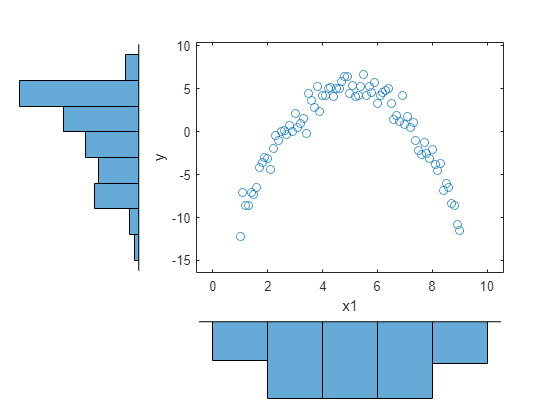

mdl2 = fitlm(x1,y1,"linear"); %in questo caso facciamo la regressione lineare==>
% dal grafico sotto si vede che i residui non sono con distribuzione
% normale e che il grafico ha una forma a U capovolta.
scatterhist(x1,mdl2.Residuals.Raw,"Direction","out","Location","SouthWest")

### Onderfitting

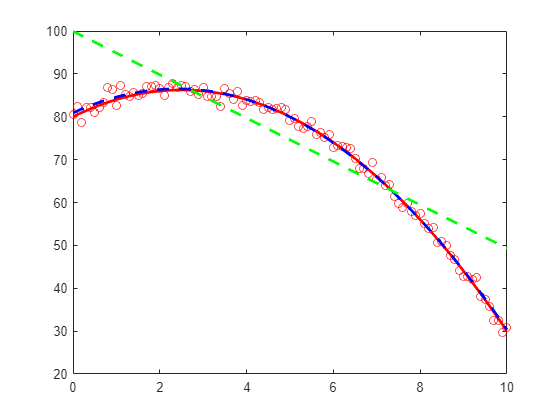

yr1 = predict(mdl1,x');
yr2 = predict(mdl2,x');
figure
plot(x,y,"r","LineWidth",2);
hold on
plot(x,yn,"or");
plot(x,yr1,"--b","LineWidth",2);
plot(x,yr2,"--g","LineWidth",2);
hold off

### Overfitting

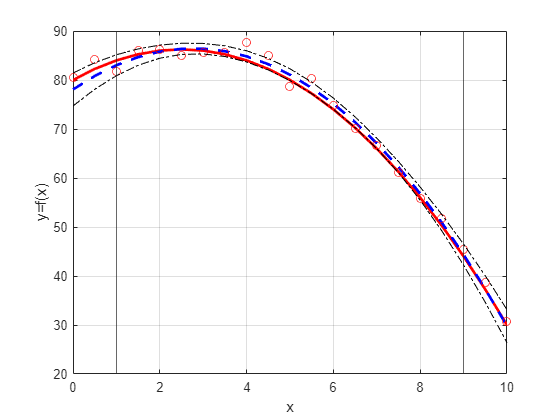

rng(0);
x=0:0.5:10;
a=-1;
b=5;
c=80;
y=a*x.^2 + b*x +c;
yn= y + random("Normal",0,1,1,numel(x));
x1=x(x >= 1 & x<=9);
y1=yn(x >= 1 & x<=9);
mdl = fitlm(x1,y1,"poly2");
[yhat,ci]=predict(mdl,x',"Alpha",0.05,"Prediction","curve");
figure
plot(x,y,"-r","LineWidth",2);
hold on
plot(x,yhat,"--b","LineWidth",2);
plot(x,yn,"or");
plot(x,ci,"-.k");
xline(1);
xline(9);
hold off
grid();
xlabel x;
ylabel y=f(x);

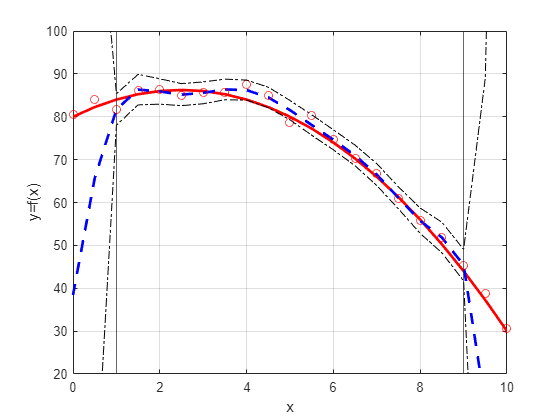

mdl=fitlm(x1,y1,"poly9");
[yhat,ci]=predict(mdl,x',"Alpha",0.05,"Prediction","curve");
figure
plot(x,y,"-r","LineWidth",2);
hold on
plot(x,yhat,"--b","LineWidth",2);
plot(x,yn,"or");
plot(x,ci,"-.k");
xline(1);
xline(9);
ylim([20,100])
hold off
grid();
xlabel x;
ylabel y=f(x);

## Taratura statica

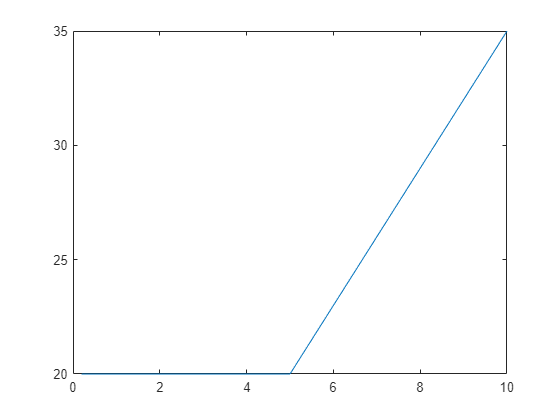

rng(10)
tbl = table();
rep = 5;
n=10;
noise = 3;
a = 2.9; %coefficiente angolare
b=0.01; %intercetta
[i,r]=meshgrid(1:n,1:rep);
tbl.r=r(:);
tbl.i=i(:);
tbl.t=((1:numel(tbl.i))/rep)';
tbl.T=max(20,tbl.t*3+5);
plot(tbl.t,tbl.T) %mostra come aumenta la temperatura

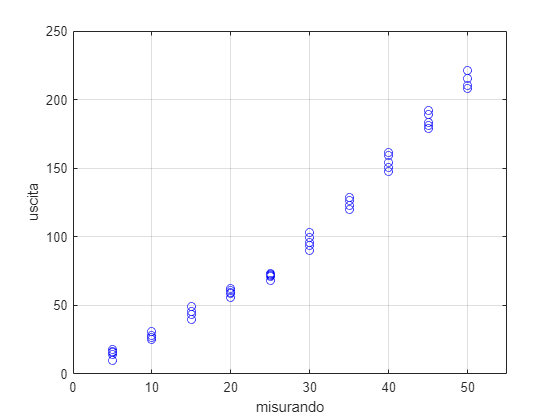

tbl.x = tbl.i * 5;
tbl.yn = a*tbl.x + b;
tbl.yT = (tbl.T - 20) * 5;
tbl.n = random("Normal", 0, noise, numel(tbl.x),1);
tbl.y = tbl.yn + tbl.yT + tbl.n; %è la somma del valote nominale, dei disturbi dovuti alla temperatura e quelli causali
tbl.ryT = tbl.yT(randperm(numel(tbl.x))); %vettore con gli stessi elementi di temperatura se facessi l'esperimento in modo casuale
tbl.ry = tbl.yn + tbl.ryT + tbl.n;%uscita conducendo gli esperimenti in maniera casuale.

plot(tbl.x, tbl.y, "ob");
xlabel misurando
ylabel uscita
xlim([0,55])
grid();

mdl = fitlm(tbl.x,tbl.y,"quadratic")

mdl = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      8.3475       2.4951    3.3456     0.0016212
    x1               1.3229      0.20841    6.3477     7.997e-08
    x1^2           0.056759    0.0036929     15.37    5.8929e-20


Number of observations: 50, Error degrees of freedom: 47
Root Mean Squared Error: 4.74
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 4.64e+03, p-value = 9.88e-55

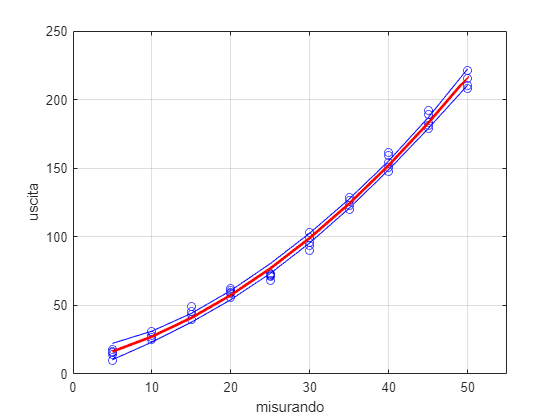

[tbl.yhat,tbl.ci] = predict(mdl,tbl.x,"Alpha", 0.01, "Prediction", "curve", "Simultaneous",true);
plot(tbl.x, tbl.y,"ob")
hold on
plot(tbl.x,tbl.yhat,"-r", "LineWidth",2)
plot(tbl.x, tbl.ci,"-b")
hold off
xlabel misurando
ylabel uscita
xlim([0,55])
grid();

mdl = fitlm(tbl.x,tbl.ry,"quadratic")

mdl = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                   Estimate        SE        tStat       pValue  
                   _________    ________    ________    _________

    (Intercept)       10.708      13.979     0.76598      0.44752
    x1                 3.808      1.1676      3.2613    0.0020676
    x1^2           -0.016696    0.020689    -0.80697      0.42375


Number of observations: 50, Error degrees of freedom: 47
Root Mean Squared Error: 26.6
R-squared: 0.723,  Adjusted R-Squared: 0.711
F-statistic vs. constant model: 61.3, p-value = 8.02e-14

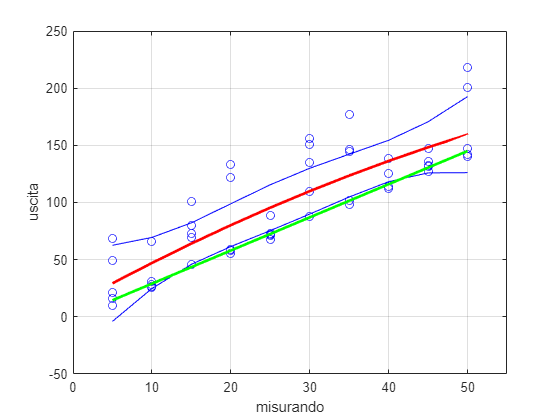

[tbl.ryhat,tbl.rci] = predict(mdl,tbl.x,"Alpha", 0.01, "Prediction", "curve", "Simultaneous",true);
plot(tbl.x, tbl.ry,"ob")
hold on
plot(tbl.x,tbl.ryhat,"-r", "LineWidth",2)
plot(tbl.x, tbl.rci,"-b")
rl=refline(a,b);
rl.Color="Green";
rl.LineWidth=2;
hold off
xlabel misurando
ylabel uscita
xlim([0 55])
grid();

## Metodo Monte Carlo

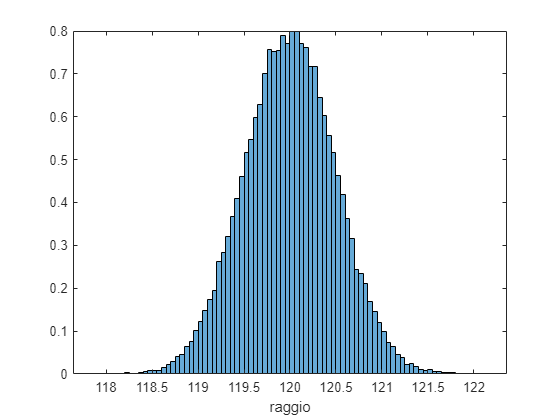

rng default;
N = 50000;
rbar = 120;
ur = 0.5;
lbar = 450;
ul = 0.5;
r = random("Normal",rbar,ur,N,1);
l = pearsrnd(lbar, ul, 0.8, 3, N, 1);

histogram(r,"Normalization","pdf");
xlabel raggio;

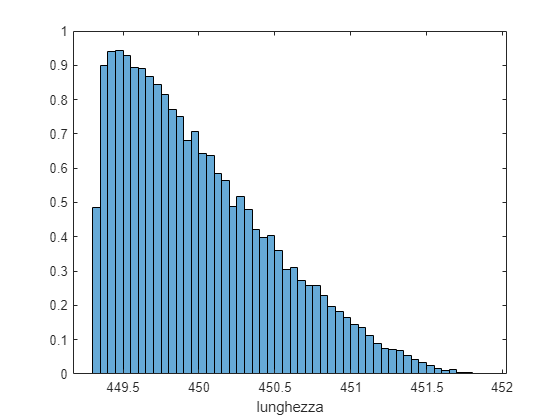

histogram(l,"Normalization","pdf");
xlabel lunghezza;

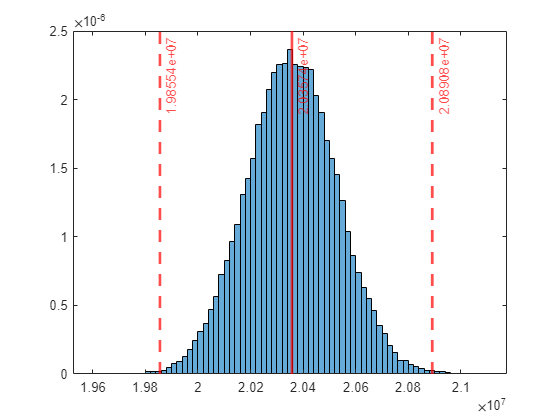

V=pi * r.^2 .* l;
alpha= 1-0.9973;
cl=quantile(V,[alpha/2, 1-alpha/2]);
histogram(V,"Normalization","pdf");
xline(mean(V), "r-", mean(V), "Linewidth",2);
xline(cl(1),"--r",cl(1),"LineWidth",2);
xline(cl(2),"--r",cl(2),"LineWidth",2);

std(V)

ans = 1.7034e+05

mean(V)

ans = 2.0357e+07